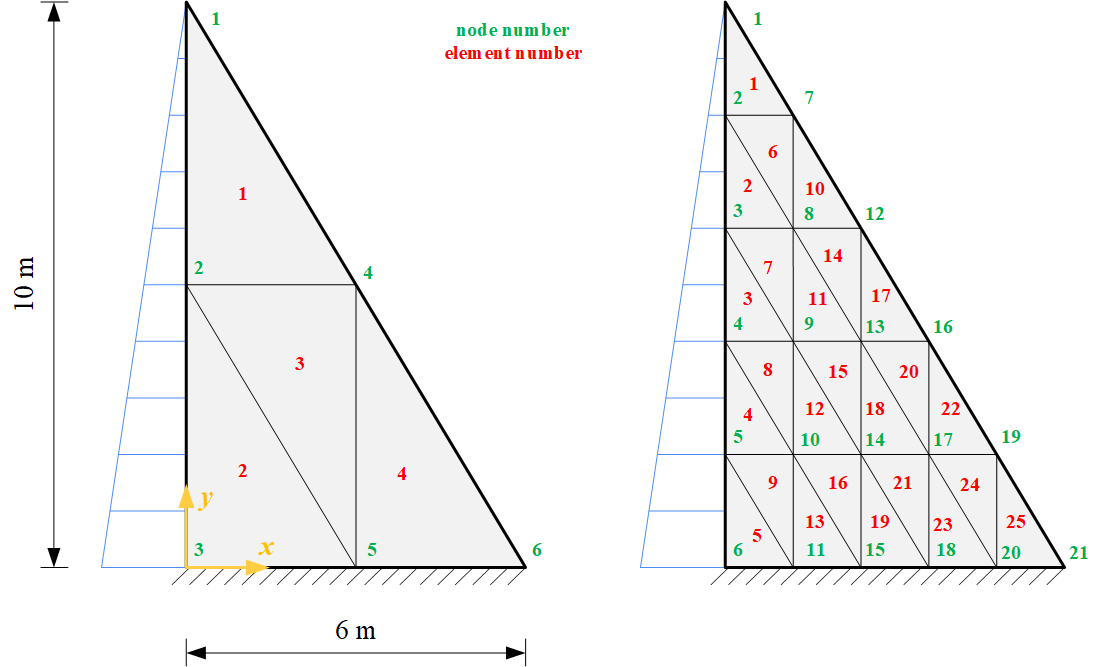

clear;clc
E = 3e10;
mu = 0.3;
t = 1;
type = 2;

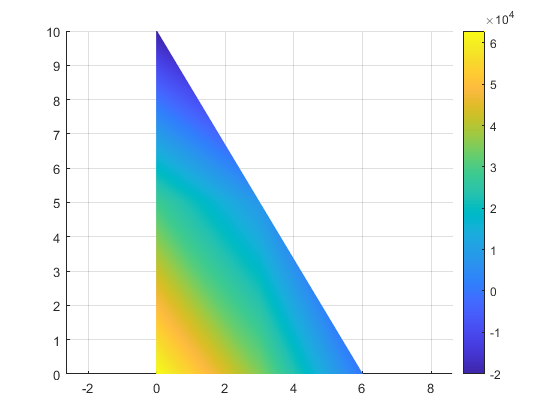

load('example_4elem.mat')
[K,A] = getTriangleK(node,elem,E,mu,t,type);
q = [1 0 0
    2 5e4*t 0
    3 10e4*t 0];
F = distriQs(node,q);
cons = [5 0; 6 0; 10 0; 12 0];
d1 = solveTriangle(K,F,cons);
[epsi1,sigm1] = solveStrAll(node,elem,A,d1,E,mu,type);
showResult(node,elem,sigm1(:,1))

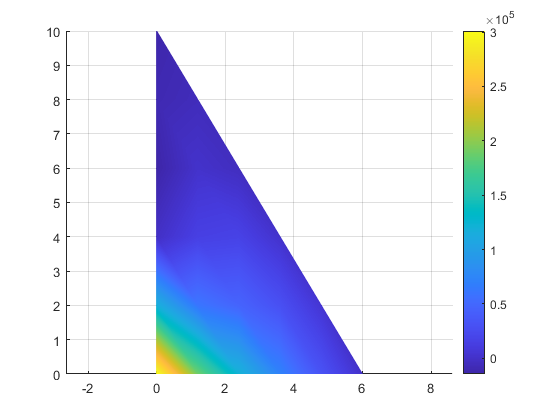

load('example_25elem.mat')
[K,A] = getTriangleK(node,elem,E,mu,t,type);
q = [1 0 0
    2 2e4*t 0
    3 4e4*t 0
    4 6e4*t 0
    5 8e4*t 0
    6 10e4*t 0];
F = distriQs(node,q);
cons = [11 0
        12 0
        22 0
        30 0
        36 0
        40 0
        42 0];
d2 = solveTriangle(K,F,cons);
[epsi2,sigm2] = solveStrAll(node,elem,A,d2,E,mu,type);
showResult(node,elem,sigm2(:,1))